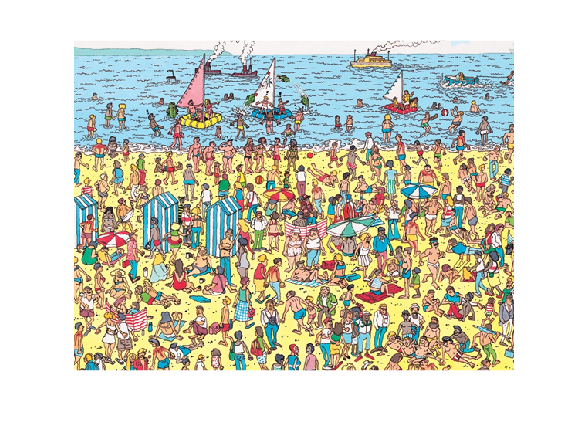

A = imread('Wally.png');
imshow(A);

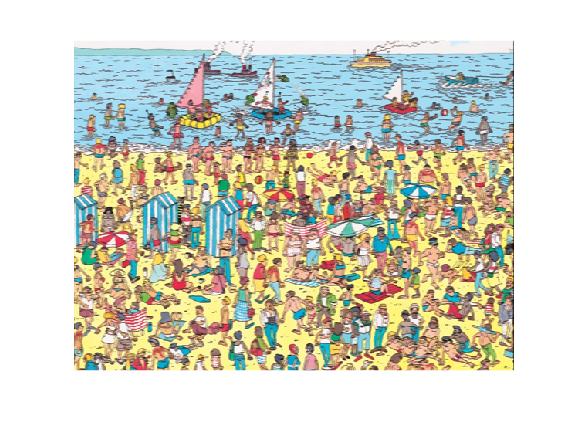

A(:,:,1) = medfilt2(A(:,:,1),[1,4]);
A(:,:,2) = medfilt2(A(:,:,2),[1,4]);
A(:,:,3) = medfilt2(A(:,:,3),[1,4]);
imshow(A);

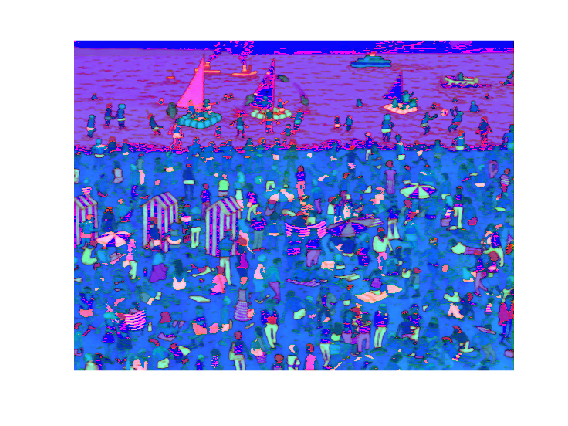

HSV = rgb2hsv(A);
GREY = rgb2gray(A);
imshow(HSV);

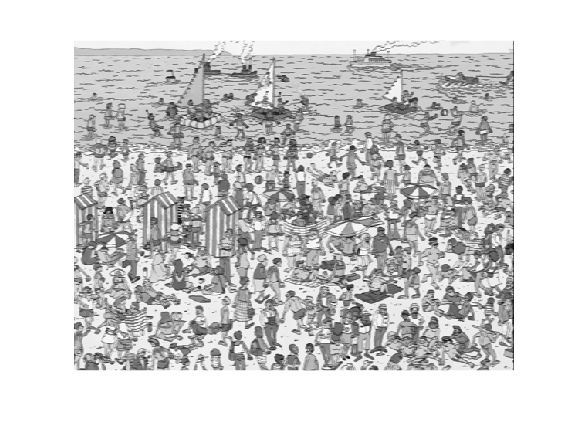

imshow(GREY);

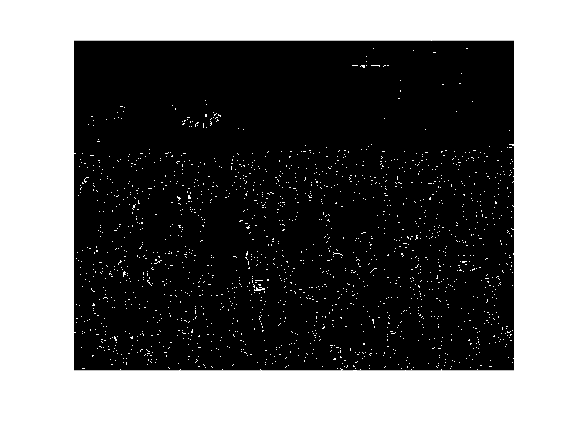

%50/360 = 0.138 +- 0.1 --> 0.12/0.14
YELLOW = HSV(:,:,1) >= 0.131 & HSV(:,:,1) <= 0.14;
imshow(YELLOW);

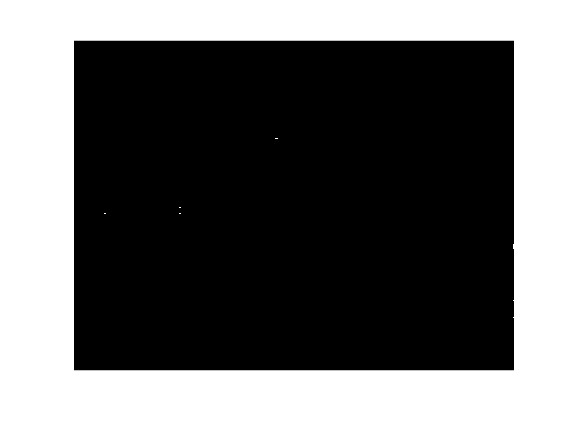

BLACK = HSV(:,:,3) < 0.09;
imshow(BLACK);

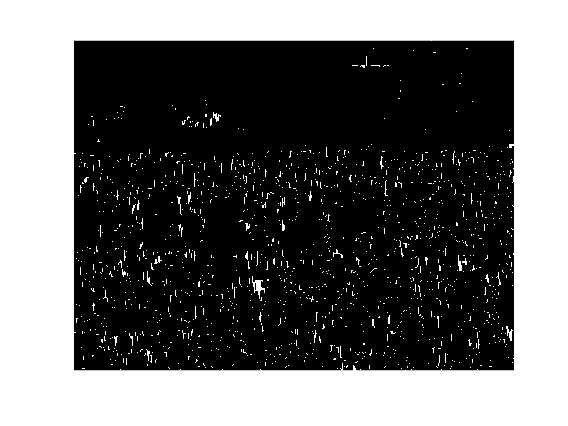

SE7 = strel('line',7,90);
YELLOW = imclose(YELLOW,SE7);
imshow(YELLOW);

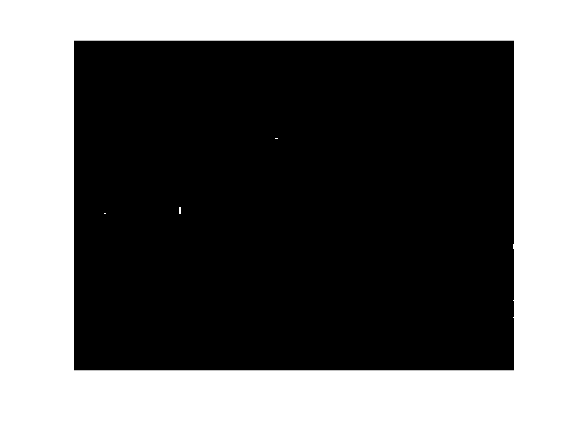

BLACK = imclose(BLACK,SE7);
imshow(BLACK);

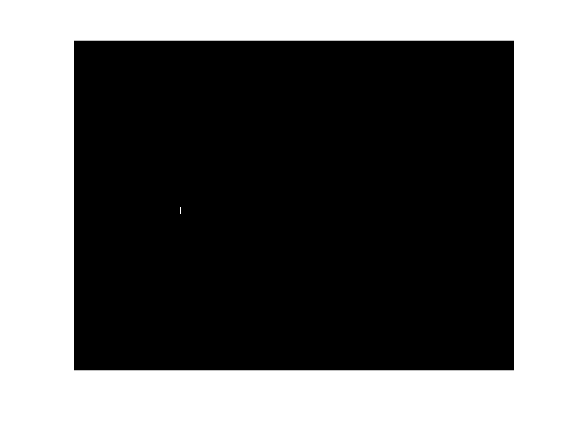

RES = YELLOW & BLACK;
imshow(RES);

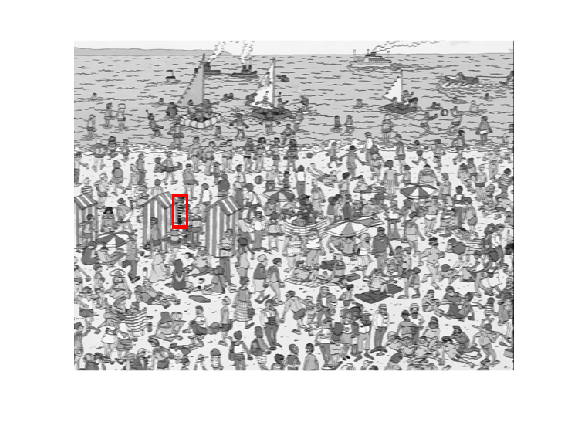

BIG = strel('rectangle',[30,15]);
LITTLE = strel('rectangle',[10,7]);
RES1 = imdilate(RES,BIG);
RES2 = imdilate(RES1,LITTLE);
RES = (imsubtract(RES2,RES1));
RES = imoverlay(GREY,RES, 'red');
imshow(RES);